# Experiment 4: Transfer Learning with ResNet-50

## Clear Environment

close all;
clear variables;
existing_GUIs = findall(0);
if length(existing_GUIs) > 1
    delete(existing_GUIs);
end
clc;

## Set folder path

folder = "C:\Users\u3253992\workspace\computer-vision\assignment_1\u3253992_assgn_1_best\CUB_200_2011\";

## Load All Images

imgFolder = folder + "images/";
imgTxtFolder = folder + "images.txt";
imageDS = imageDatastore(imgFolder, "IncludeSubfolders",true, "LabelSource","foldernames");
[f1, f2, f3, f4, f5] = splitEachLabel(imageDS, 0.2, 0.2, 0.2, 0.2);

numFolds = 5;
numClasses = 200;

## Load pretrained ResNet-50

requires Deep Learning Toolbox Model for ResNet-50

net       = resnet50;                                
inputSize = net.Layers(1).InputSize;
targetSize = inputSize(1:2);

## Build the layer graph and swap out the last 3 layers

lgraph = layerGraph(net);

% 1) New fully‐connected layer (20 classes)
newFc = fullyConnectedLayer(numClasses, ...
    'Name','fc20', ...
    'WeightLearnRateFactor',10, ...
    'BiasLearnRateFactor',10);

% 2) New softmax
newSoftmax = softmaxLayer('Name','softmax20');

% 3) New classification output
newClassOutput = classificationLayer('Name','classoutput20');

% Replace them
lgraph = replaceLayer(lgraph, 'fc1000', newFc);
lgraph = replaceLayer(lgraph, 'fc1000_softmax', newSoftmax);
lgraph = replaceLayer(lgraph, 'ClassificationLayer_fc1000', newClassOutput);

## Enable GPU

[device, useGPU] = enableGPU();

✅ GPU found and ready:
  CUDADevice with properties:

                 Name: 'NVIDIA GeForce RTX 3070'
                Index: 1 (of 1)
    ComputeCapability: '8.6'
          DriverModel: 'WDDM'
          TotalMemory: 8589410304 (8.59 GB)
      AvailableMemory: 7443034112 (7.44 GB)
      DeviceAvailable: true
       DeviceSelected: true

  Show 

## Train the simple CNN model for each fold

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:52 |        3.12% |        0.68% |       5.3370 |       5.9234 |      1.0000e-04 |
|       1 |          50 |       00:01:16 |       28.12% |              |       3.1717 |              |      1.0000e-04 |
|       1 |         100 |       00:01:40 |       53.12% |              |       2.1856 |              |      1.0000e-04 |
|       1 |         150 |       00:02:05 |       68.75% |              |       1.4573 |              |      1.0000

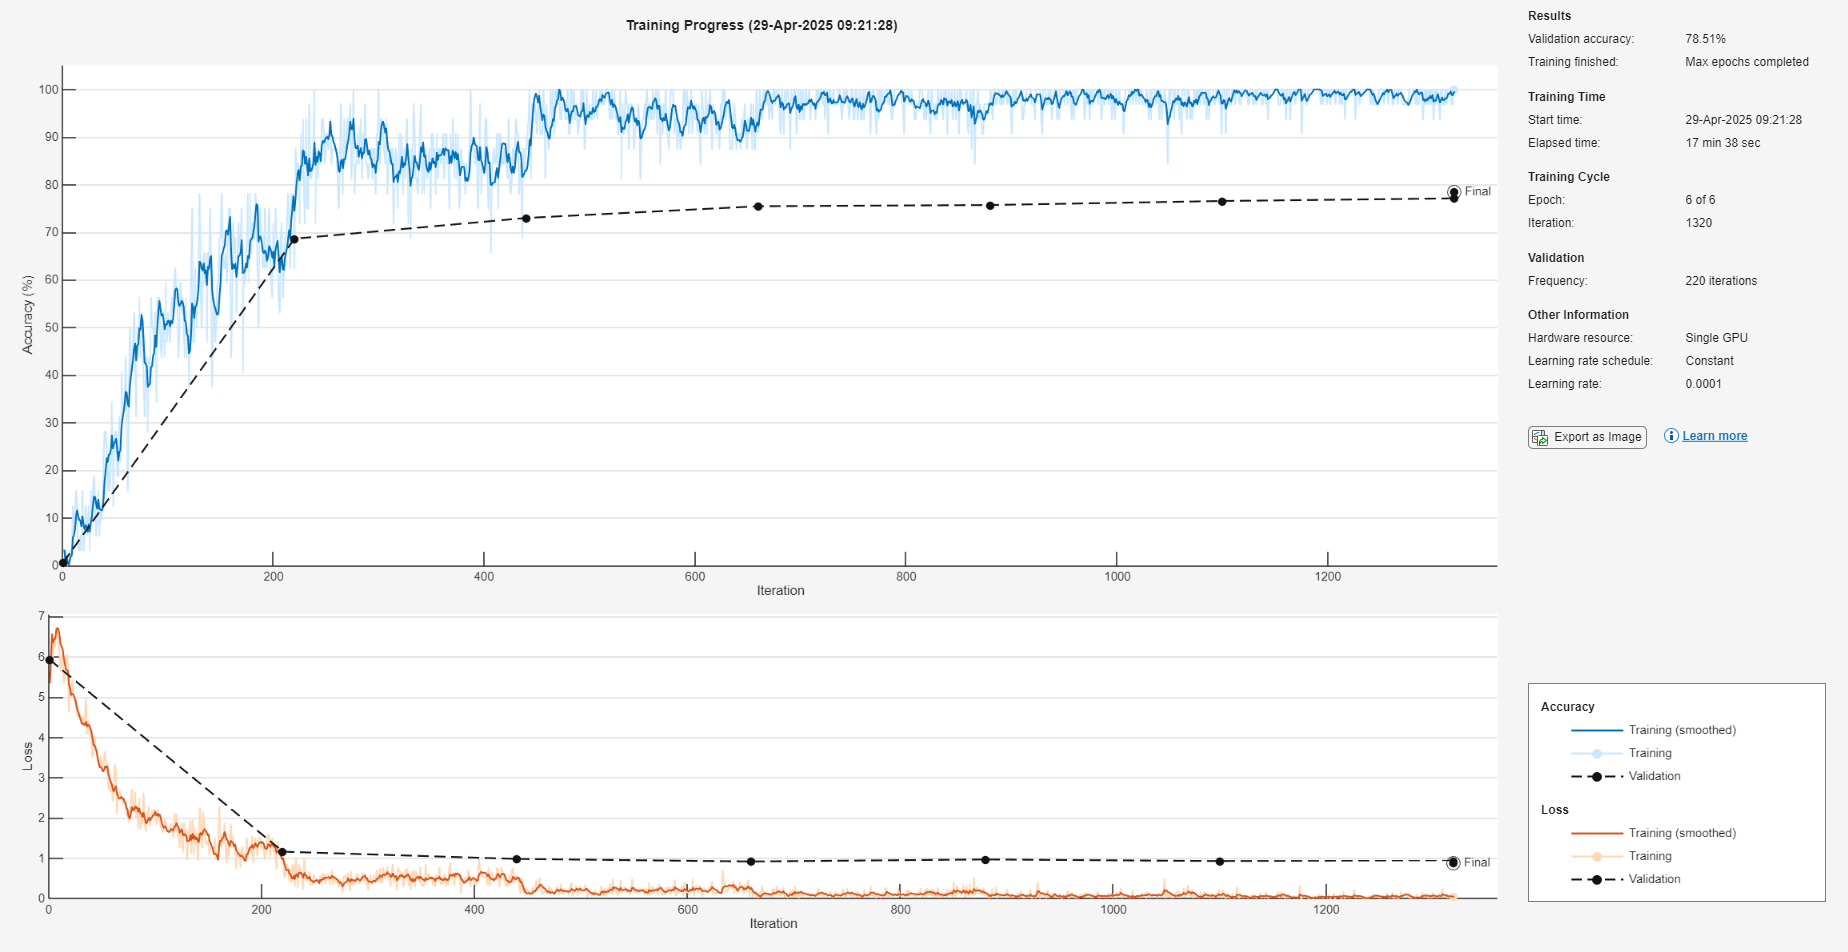

Accuracy for Run 1 is: 0.7891


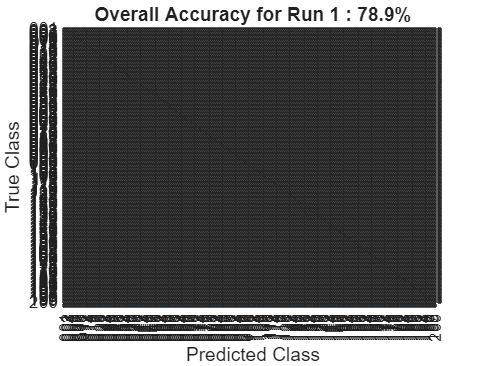

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:40 |        0.00% |        1.01% |       5.4732 |       5.8162 |      1.0000e-04 |
|       1 |          50 |       00:01:05 |       28.12% |              |       3.1286 |              |      1.0000e-04 |
|       1 |         100 |       00:01:31 |       46.88% |              |       1.7983 |              |      1.0000e-04 |
|       1 |         150 |       00:01:57 |       71.88% |              |       1.0005 |              |      1.0000

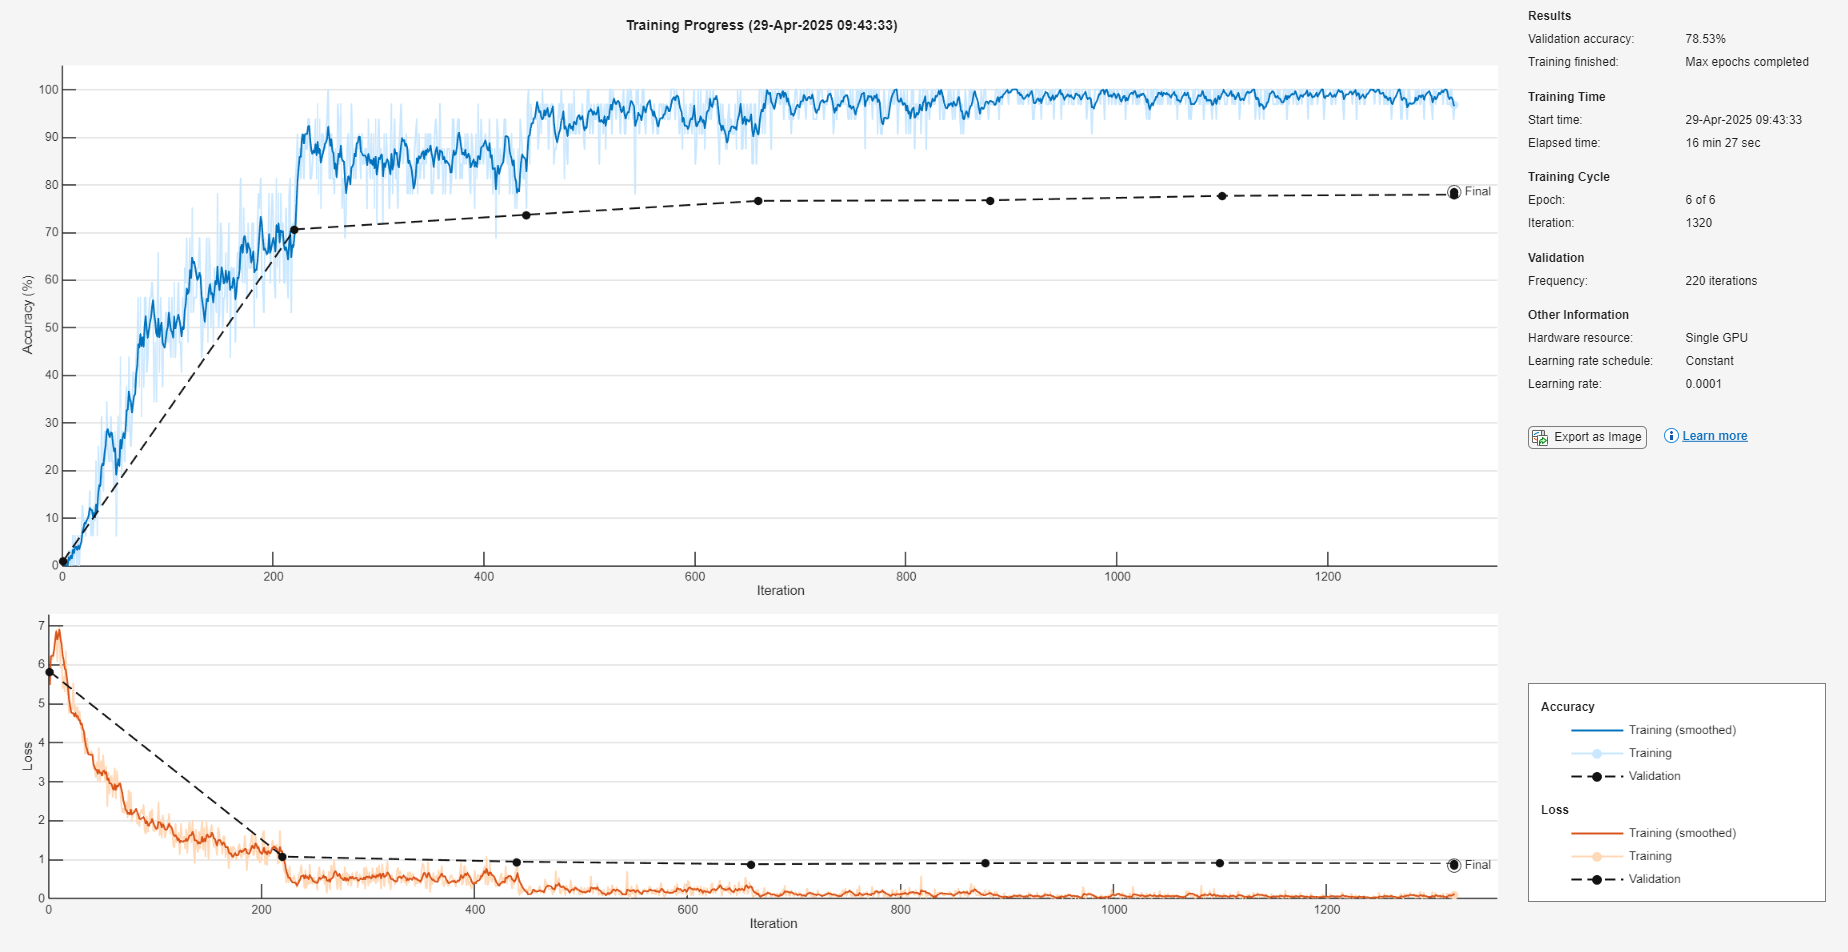

Accuracy for Run 2 is: 0.78022


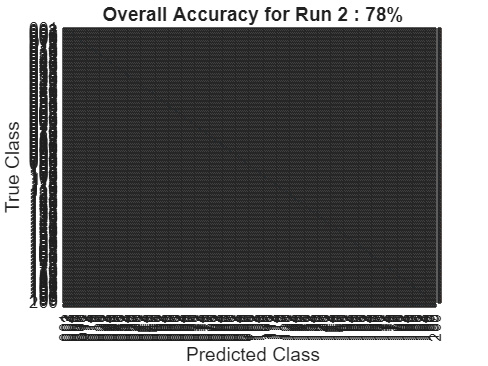

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:25 |        0.00% |        0.93% |       5.9200 |       5.8399 |      1.0000e-04 |
|       1 |          50 |       00:00:49 |       31.25% |              |       2.7805 |              |      1.0000e-04 |
|       1 |         100 |       00:01:13 |       56.25% |              |       1.6876 |              |      1.0000e-04 |
|       1 |         150 |       00:01:37 |       59.38% |              |       1.4165 |              |      1.0000

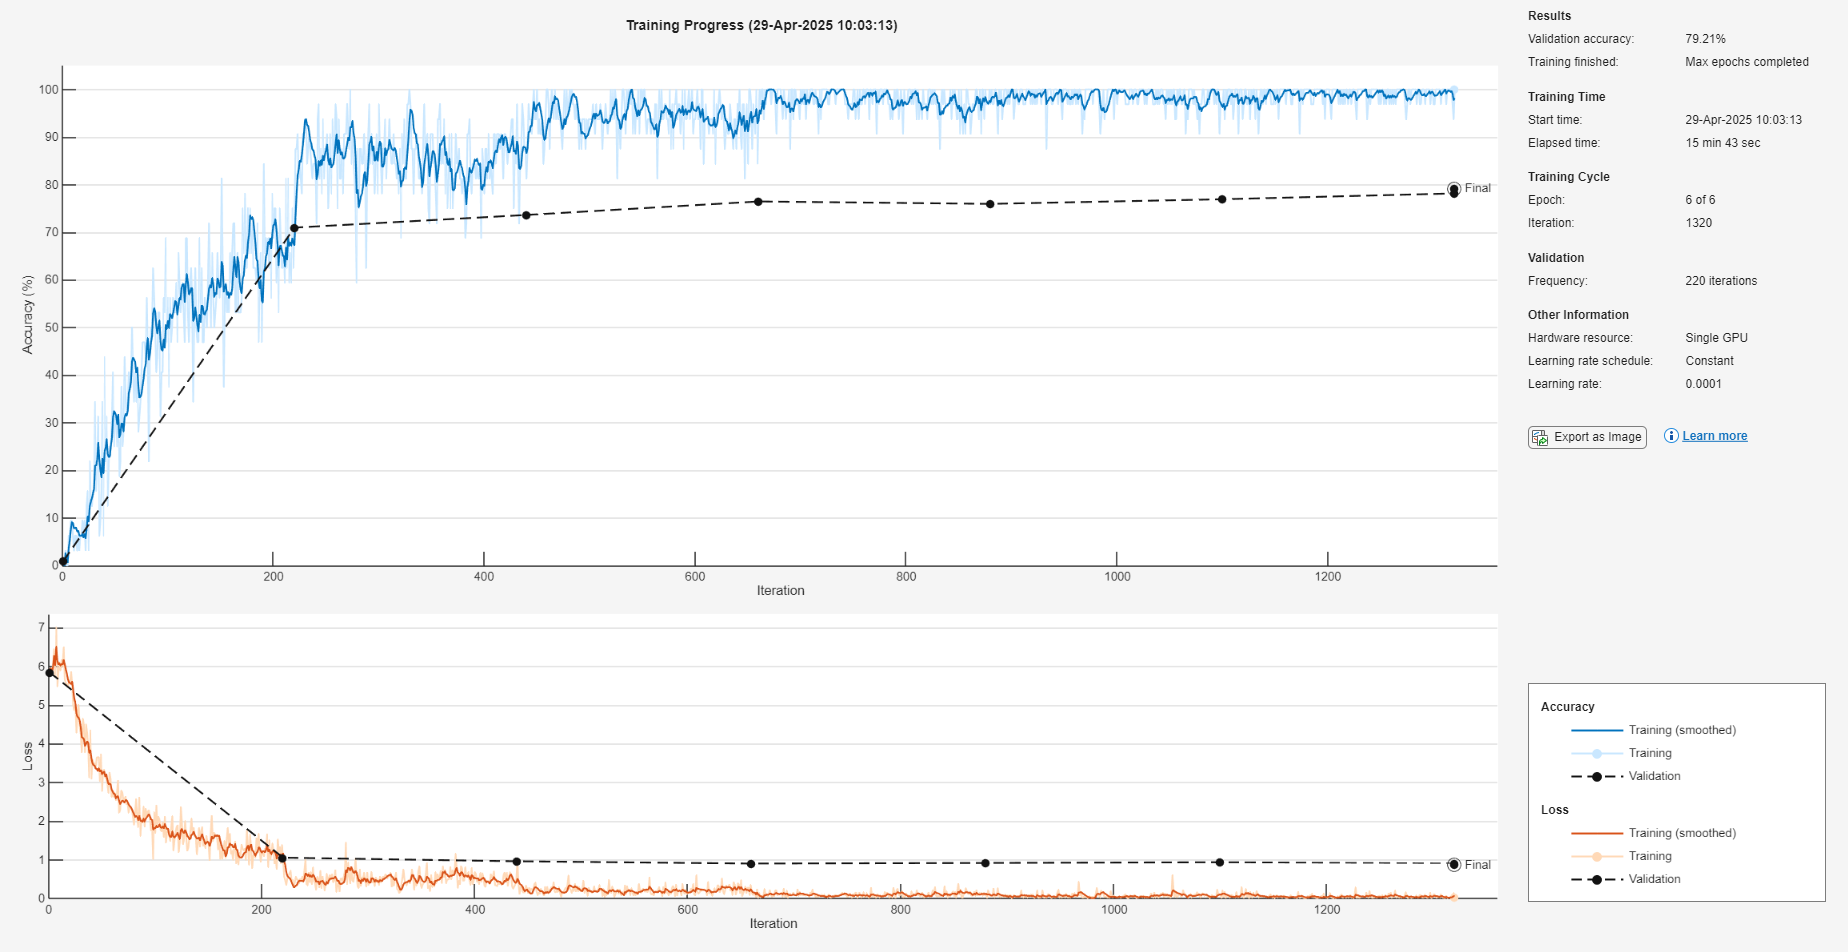

Accuracy for Run 3 is: 0.78253


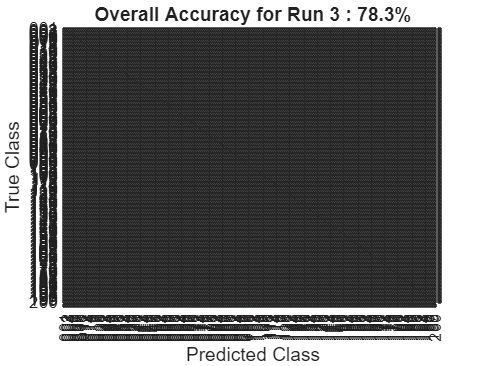

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:24 |        0.00% |        0.97% |       5.9150 |       5.8431 |      1.0000e-04 |
|       1 |          50 |       00:00:48 |       31.25% |              |       3.2978 |              |      1.0000e-04 |
|       1 |         100 |       00:01:19 |       56.25% |              |       1.8393 |              |      1.0000e-04 |
|       1 |         150 |       00:01:44 |       59.38% |              |       1.5173 |              |      1.0000

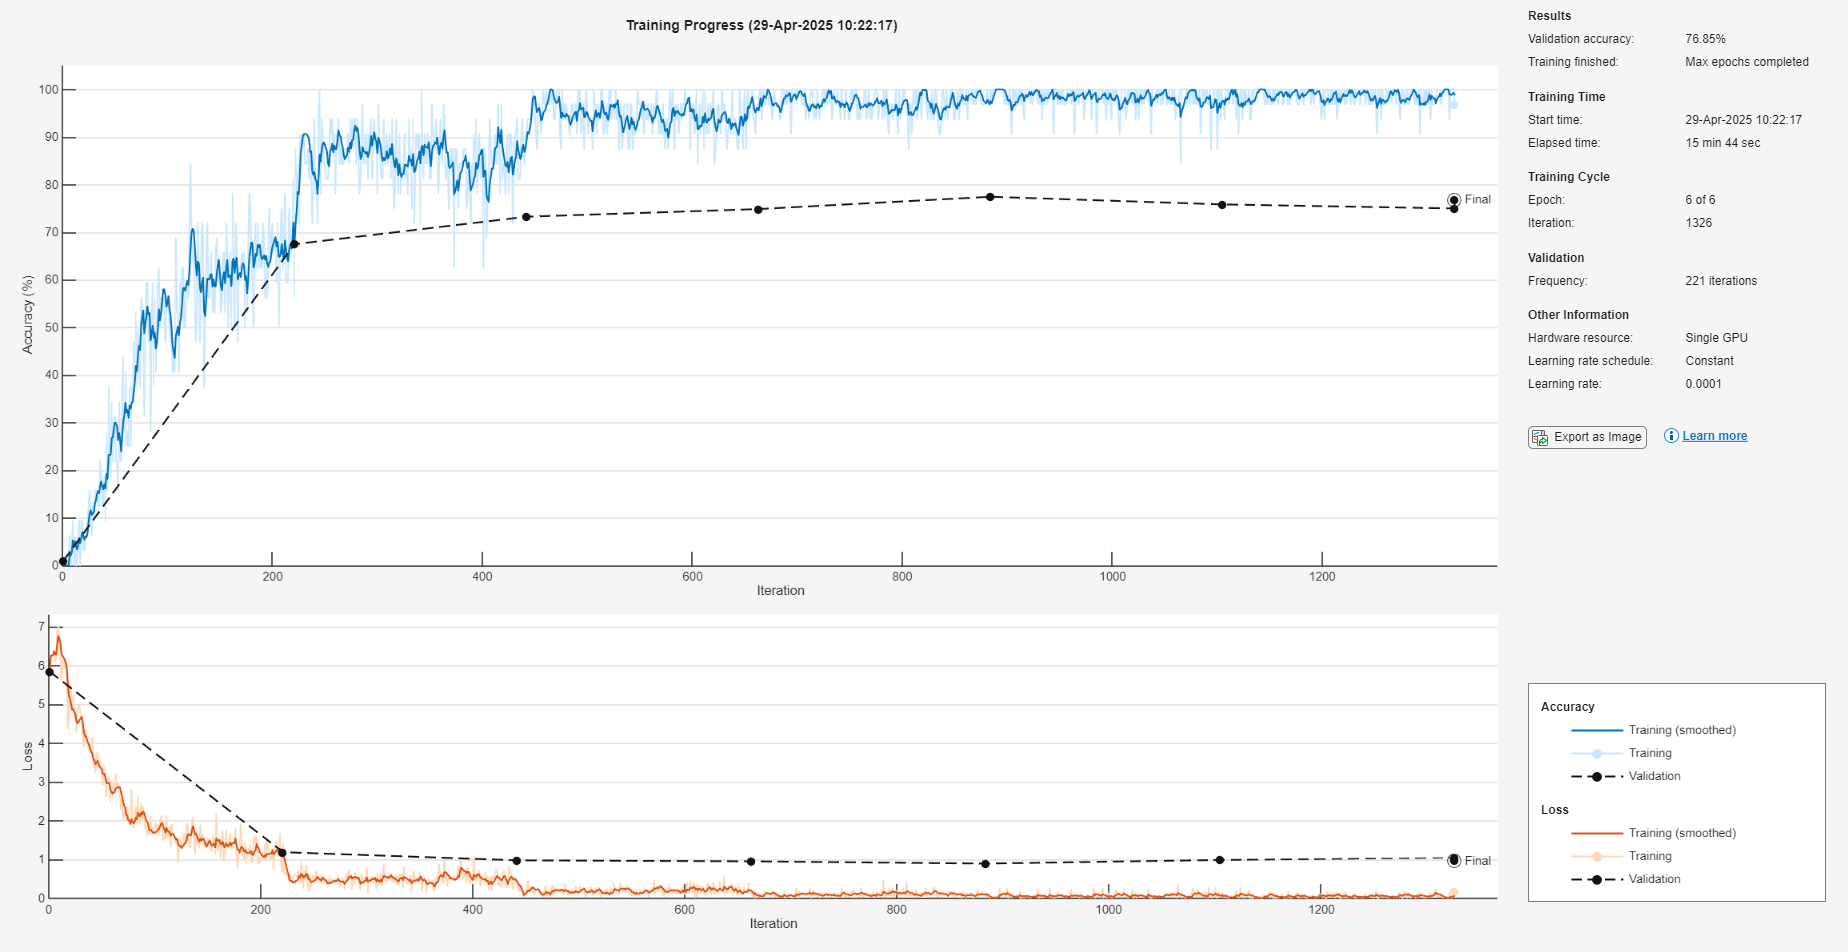

Accuracy for Run 4 is: 0.78272


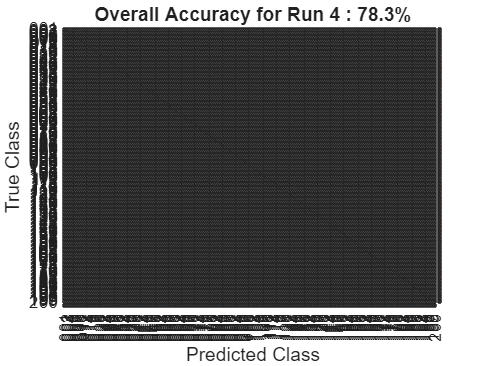

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:42 |        0.00% |        1.03% |       5.6421 |       5.8245 |      1.0000e-04 |
|       1 |          50 |       00:01:16 |       25.00% |              |       3.4754 |              |      1.0000e-04 |
|       1 |         100 |       00:01:50 |       53.12% |              |       2.2663 |              |      1.0000e-04 |
|       1 |         150 |       00:02:23 |       53.12% |              |       1.6397 |              |      1.0000

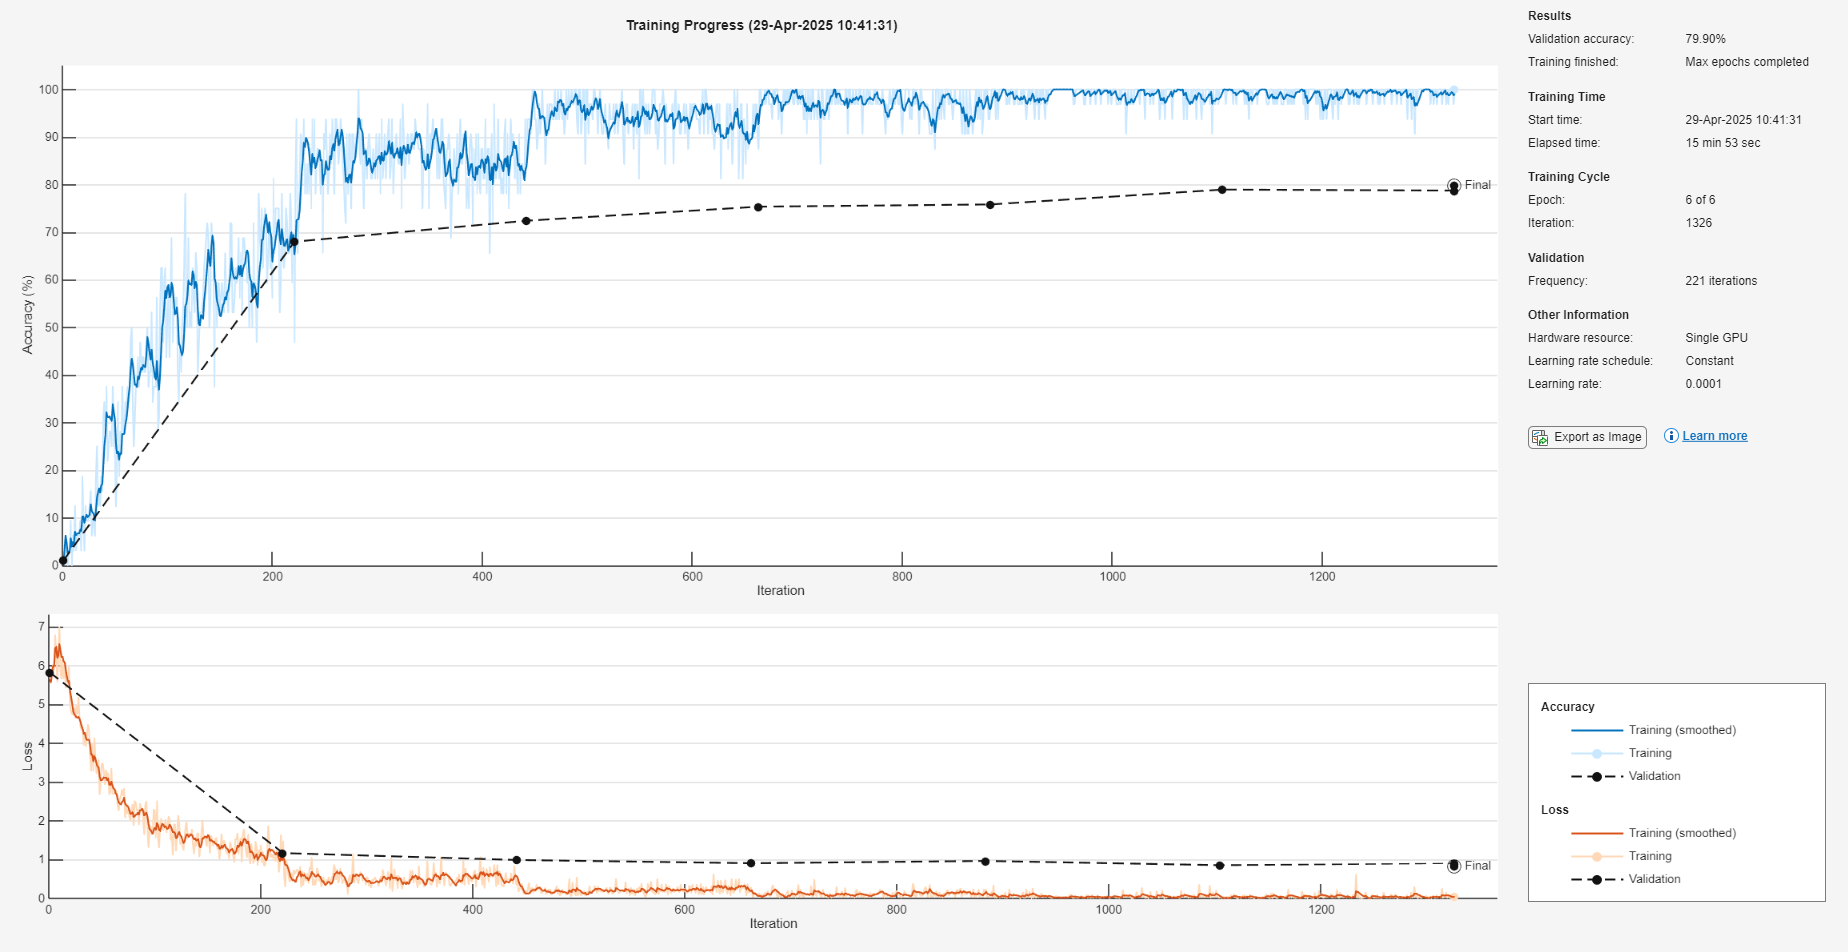

Accuracy for Run 5 is: 0.78042


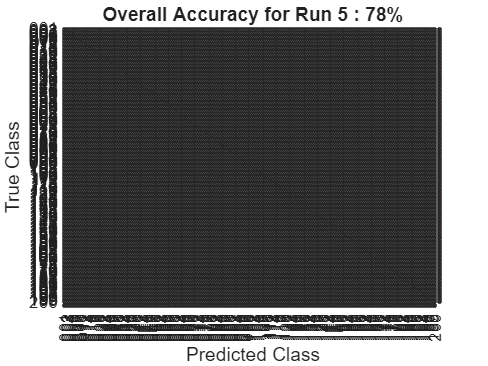

accuracy_overall = 0.0;
for i = 1:numFolds
    [cdsTraining, cdsValidation, cdsTest, trainingImageDS, validationImageDS, testImageDS] = ...
        getFoldsFor5FoldCrossVal(i, f1, f2, f3, f4, f5, folder, imgTxtFolder, targetSize);

    % Set the training options
    options = trainingOptions('adam', ...
    'MiniBatchSize',32, ...
    'MaxEpochs',6, ...
    'InitialLearnRate',1e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',cdsValidation, ...
    'ValidationFrequency',floor(numel(trainingImageDS.Files)/32), ...
    'Verbose',true, ...
    'Plots','training-progress', ...
    'ExecutionEnvironment','gpu');

    resnet20 = trainNetwork(cdsTraining, lgraph, options);

    YPred = classify(resnet20, cdsTest);
    YTest = testImageDS.Labels;
    
    accuracy = sum(YPred == YTest)/numel(YTest); % Output on command line
    disp("Accuracy for Run "+ string(i)+" is: " + accuracy);

    % Show confusion matrix in figure
    [m, order] = confusionmat(YTest, YPred);
    figure(i);
    cm = confusionchart(m, order, ...
        'ColumnSummary','column-normalized', ...
        'RowSummary','row-normalized');
    title("Overall Accuracy for Run "+ string(i)+" : "+ ...
        string(round(accuracy*100, 1)) +"%");

    accuracy_overall = accuracy_overall+accuracy;
end


disp("Average accuracy of five folds is "+ string(accuracy_overall/numFolds))

Average accuracy of five folds is 0.783
